fileU='02-23-2016_21_05_24_top';

addpath('../Library');
load('BGimg0223');
%Define the physical constant
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
warning('off','all');
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = VirialUnitarity( );
filefolder_Unitary='/Users/Zhenjie/Data/2016-02-23/';

filefolder_Unitary='/Users/Zhenjie/Data/2016-02-23/';

[~,~,~,VsortU,~,~,~,EFU]=EOS_Online( [filefolder_Unitary,fileU,'.fits'],'ROI1',[215,25,312,402],...
    'ROI2',[209,187,335,243],'ShowOutline',0,'TailRange',[85,325],'KappaMode',2,'PolyOrder',10,'VrangeFactor',5,'IfHalf',0,'kmax',1.1,'kmin',0.1,'Points',20,...
    'Fudge',2.92,'smooth',1,'CutOff',inf,'ShowPlot',0,'ShowOutline',0,'BGSubtraction',BGimg,'SelectByPortion',0,'Portion',0.1,...
    'IfTailTailor',1,'IfFitExpTail',1,'ExpTailPortion',0.06);


VsortU=VsortU/hh;EFU=EFU/hh;

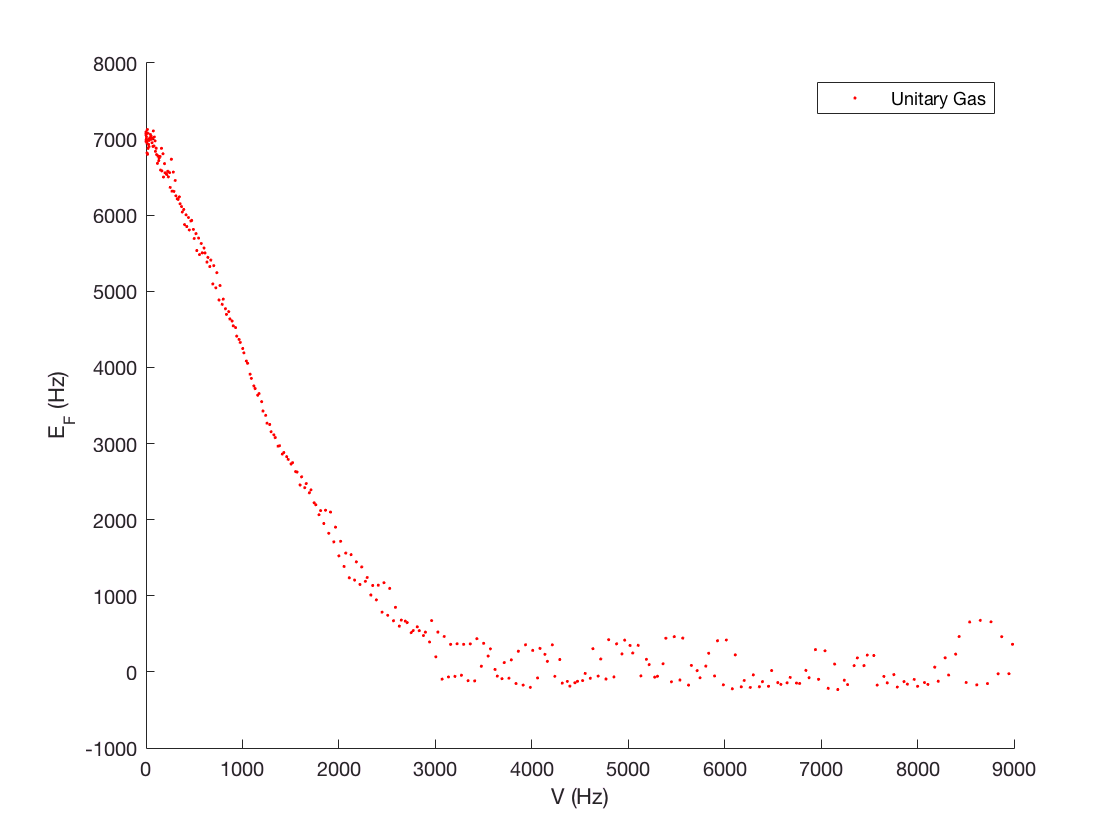

scatter(VsortU,EFU,'r.','DisplayName','Unitary Gas');
xlim([0,9000])
legend('Show')
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

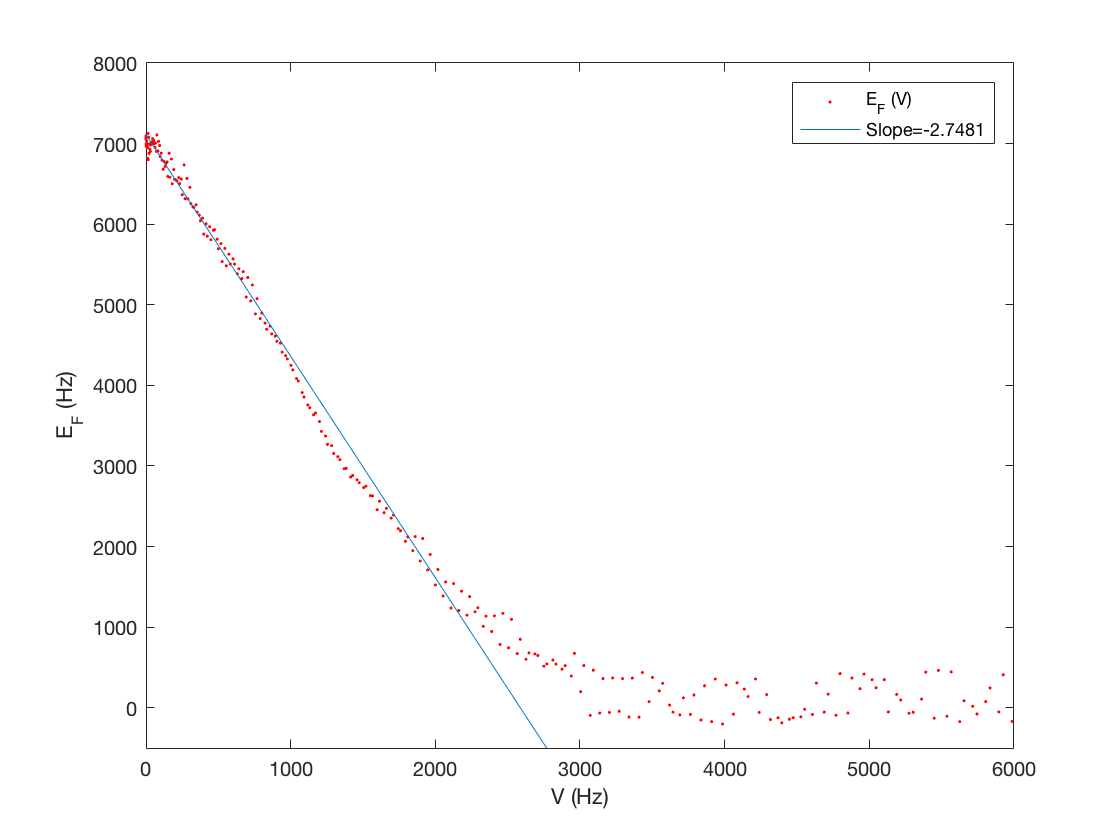

%%Unitary
FitRangeU=1000;
EFfitU=EFU(VsortU<FitRangeU);
VfitU=VsortU(VsortU<FitRangeU);

pU=polyfit(VfitU,EFfitU,1);
EFlineU=polyval(pU,VsortU);
plot(VsortU,EFU,'r.','DisplayName','E_F (V)');
xlim([0,6000]);ylim([-500,8000]);
hold on
plot(VsortU,EFlineU,'DisplayName',['Slope=',num2str(pU(1))]);
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');
legend('show');

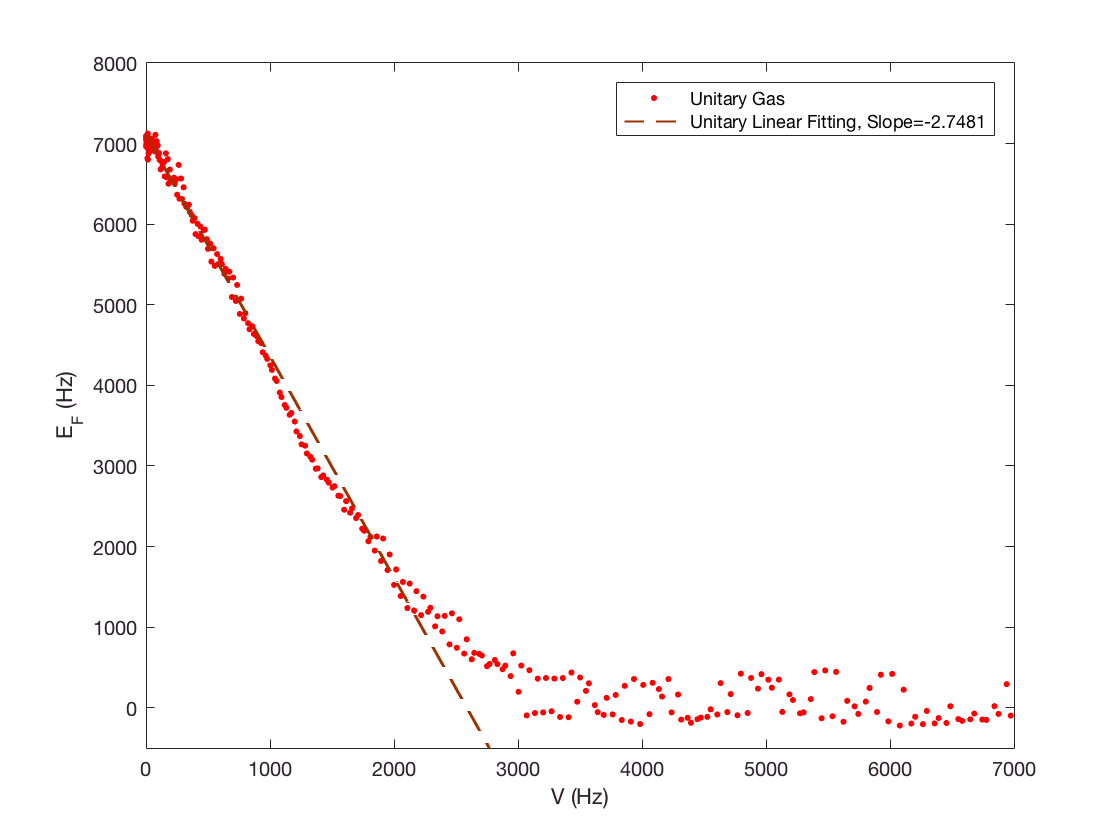

plot(VsortU,EFU,'r.','DisplayName','Unitary Gas','MarkerSize',15);
hold on
xlim([0,7000]);
plot(VsortU,EFlineU,'--','color',[0.6,0.2,0],'DisplayName',['Unitary Linear Fitting, Slope=',num2str(pU(1))],'LineWidth',1);
legend('Show')
ylim([-500,8000]);
hold off
xlabel('V (Hz)');ylabel('E_F (Hz)');

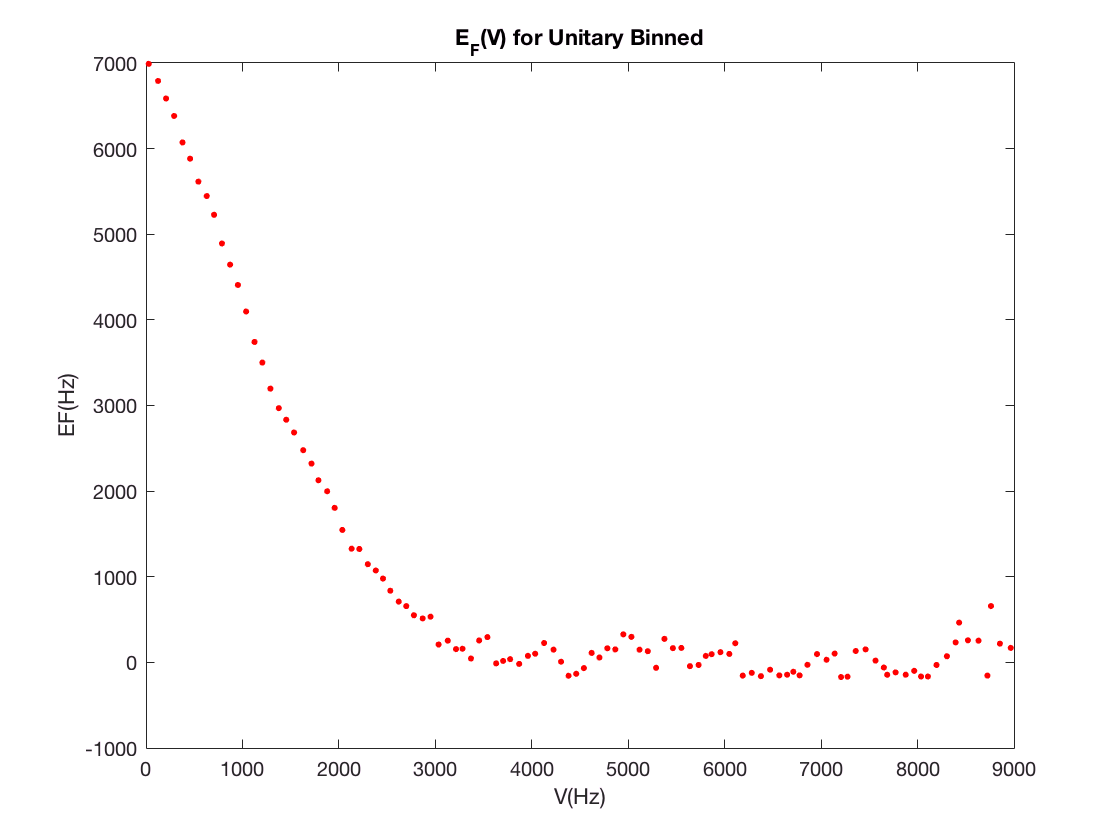

Ngrid=120;
Vgrid=linspace(0,10000,Ngrid+1);
[Vmean,EFUmean,Verr,EFerr]=BinGrid( VsortU,EFU,Vgrid,1);
plot(Vmean,EFUmean,'r.','MarkerSize',15)
xlabel('V(Hz)');ylabel('EF(Hz)')
title('E_F(V) for Unitary Binned');
xlim([0,9000])

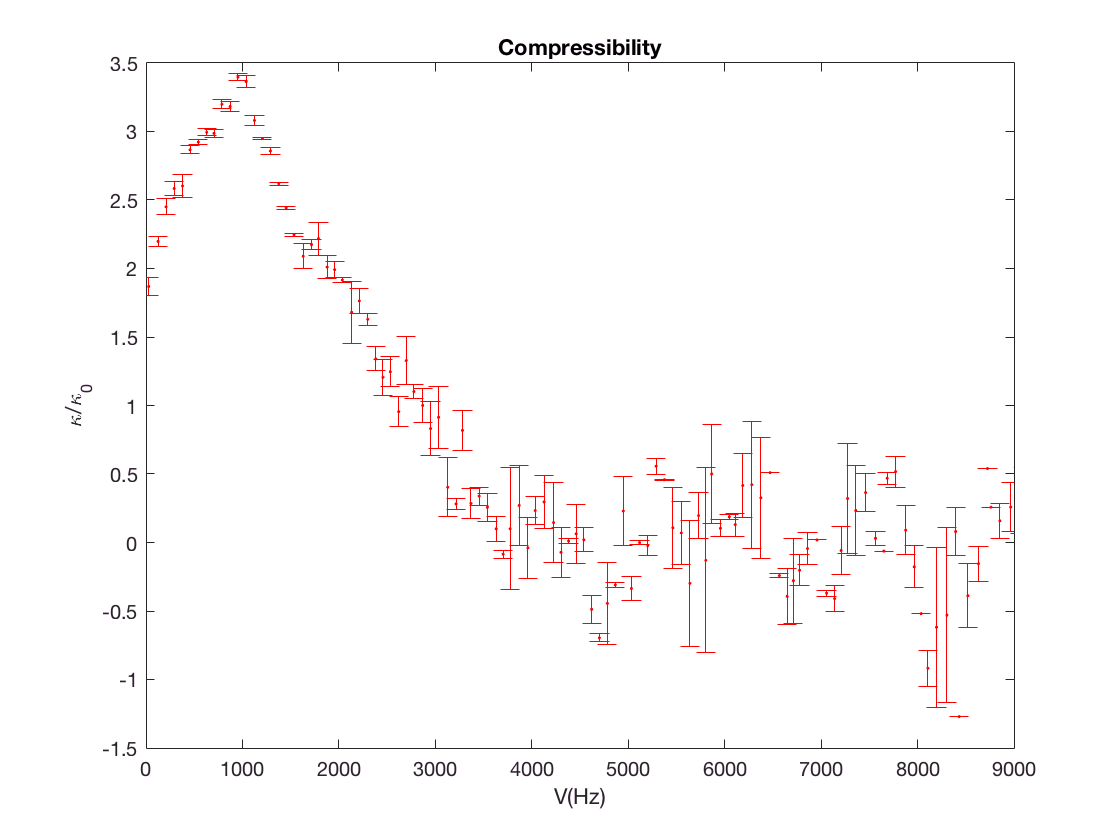


[KappaT,KappaTerr]=FiniteD( Vmean,Verr,EFUmean,EFerr,4 );
KappaT=-KappaT;
%% Get the Kappa vs V
errorbar(Vmean,KappaT,KappaTerr,'r.')
xlim([0,9000]);
xlabel('V(Hz)');ylabel('\kappa/\kappa_0')
title('Compressibility');